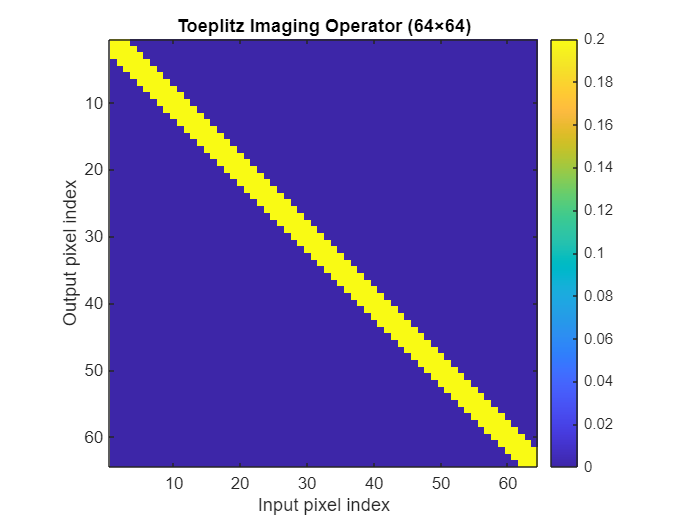

% OPTI 512 L
% LAB 7
% Mohanbabu Mani

% 1.

dim    = 64; 
numpix = 5;    
H_toeplitz  = GenToeplitz(dim, numpix);
H_circulant = GenCirculant(dim, numpix);

figure;
imagesc(H_toeplitz);
colorbar;
title('Toeplitz Imaging Operator (64×64)');
xlabel('Input pixel index');
ylabel('Output pixel index');
axis square;

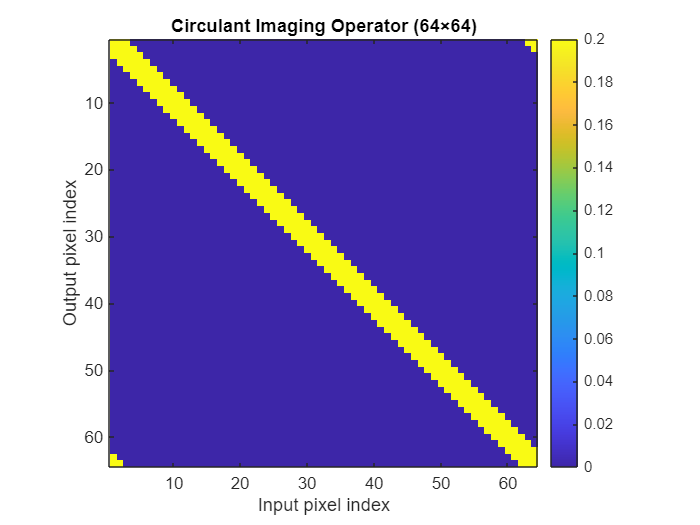


figure;
imagesc(H_circulant);
colorbar;
title('Circulant Imaging Operator (64×64)');
xlabel('Input pixel index');
ylabel('Output pixel index');
axis square;

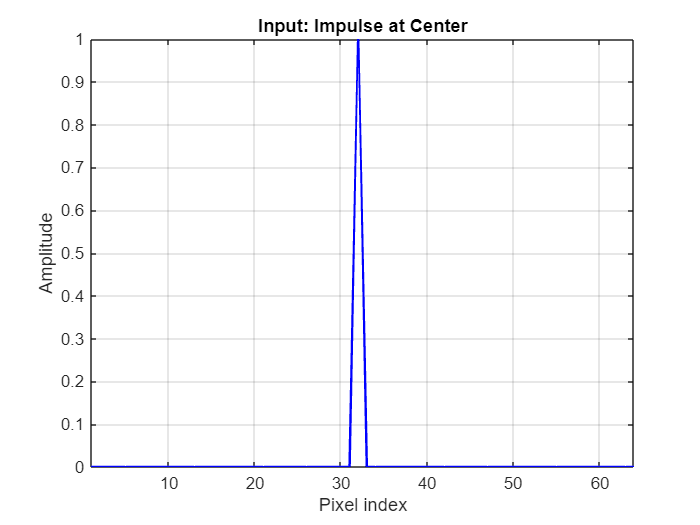


x = zeros(dim,1);
x(32) = 1;    
y_toep = H_toeplitz  * x;
y_circ = H_circulant * x;

figure;
plot(x,'b-','LineWidth',1.5); grid on;
title('Input: Impulse at Center');
xlabel('Pixel index');
ylabel('Amplitude');
xlim([1 dim]);

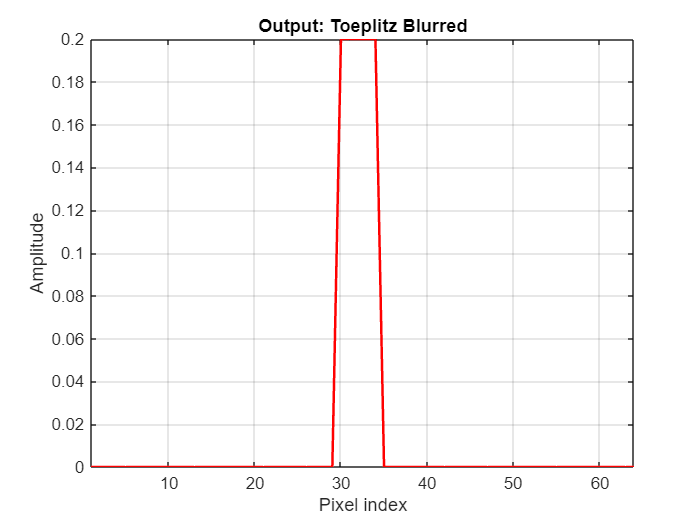


figure;
plot(y_toep,'r-','LineWidth',1.5); grid on;
title('Output: Toeplitz Blurred');
xlabel('Pixel index');
ylabel('Amplitude');
xlim([1 dim]);

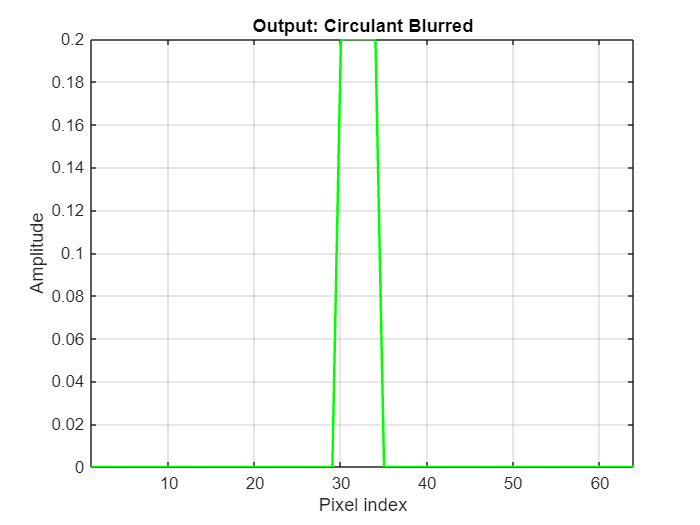


figure;
plot(y_circ,'g-','LineWidth',1.5); grid on;
title('Output: Circulant Blurred');
xlabel('Pixel index');
ylabel('Amplitude');
xlim([1 dim]);


save('imaging_operators.mat','H_toeplitz','H_circulant','dim','numpix');

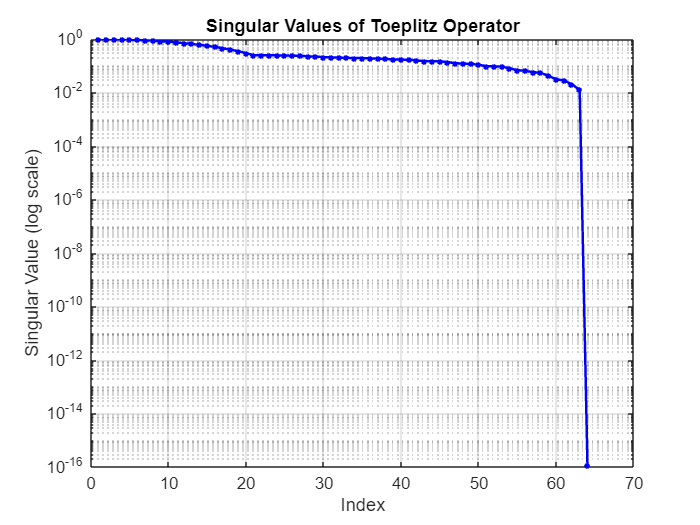

% 2.


% For real symmetric (Toeplitz) or normal (circulant) convolution operators, 
% the left and right singular vectors coincide. Convolution commutes with its adjoint 
% up to boundary conditions, making H H^T and H^T H share eigenvectors. 
% Thus U=V, and plotting the first few columns of V reproduces the same sinusoidal patterns observed in U.


dim    = 64;
numpix = 5;
H_toeplitz  = GenToeplitz(dim, numpix);
H_circulant = GenCirculant(dim, numpix);
[U_toep, S_toep, V_toep] = svd(H_toeplitz);
sigma_toep = diag(S_toep);
figure;
semilogy(sigma_toep, 'b.-', 'LineWidth', 1.5, 'MarkerSize', 10);
grid on;
title('Singular Values of Toeplitz Operator');
xlabel('Index');
ylabel('Singular Value (log scale)');

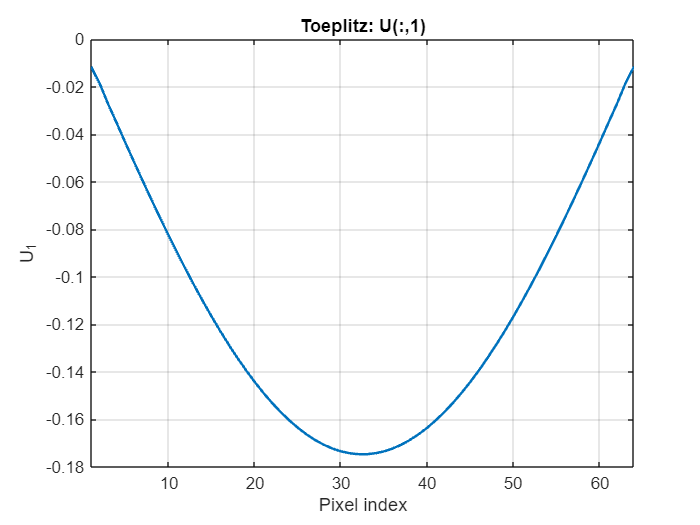

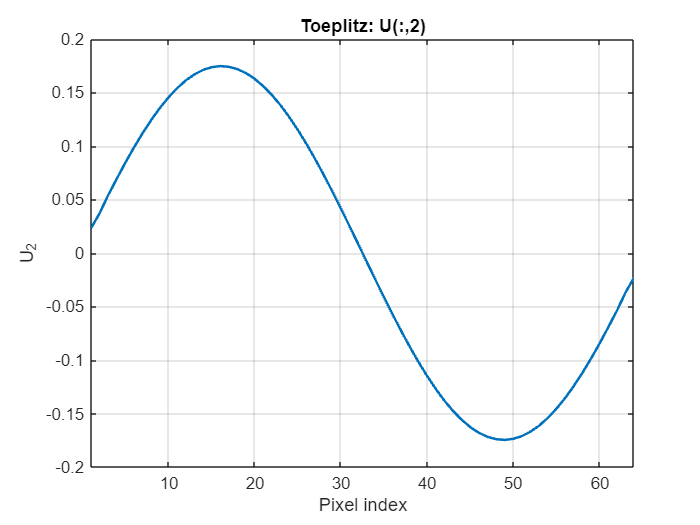

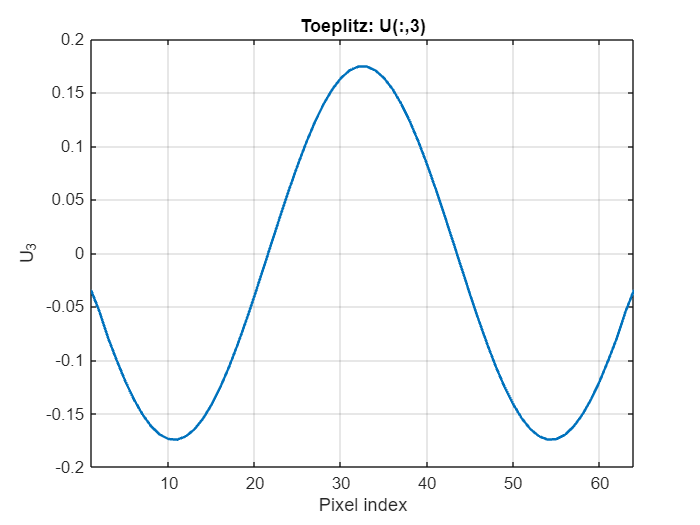

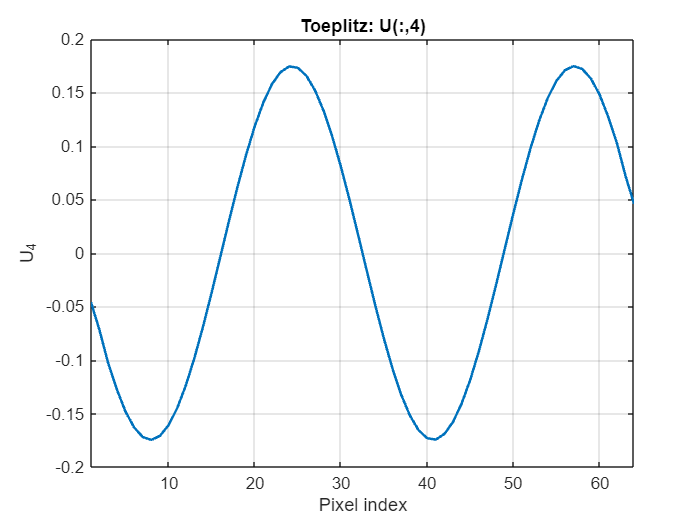

numCols = 4; 
x = 1:dim;
for k = 1:numCols
    figure;
    plot(x, U_toep(:,k), '-', 'LineWidth', 1.5);
    grid on;
    title(sprintf('Toeplitz: U(:,%d)', k));
    xlabel('Pixel index');
    ylabel(sprintf('U_{%d}', k));
    xlim([1 dim]);
end

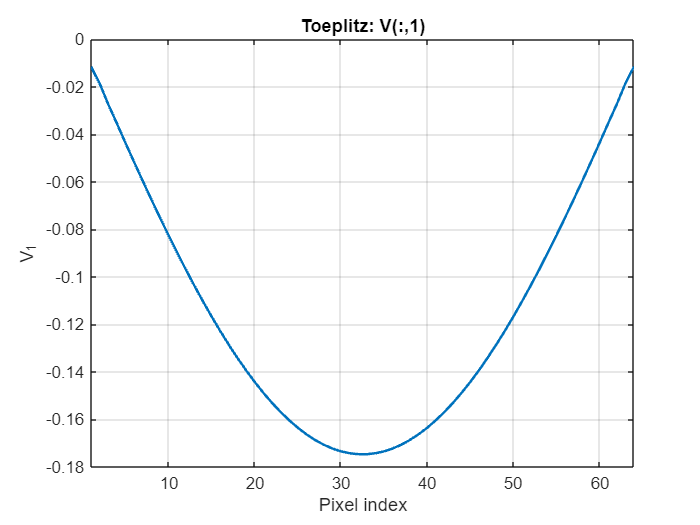

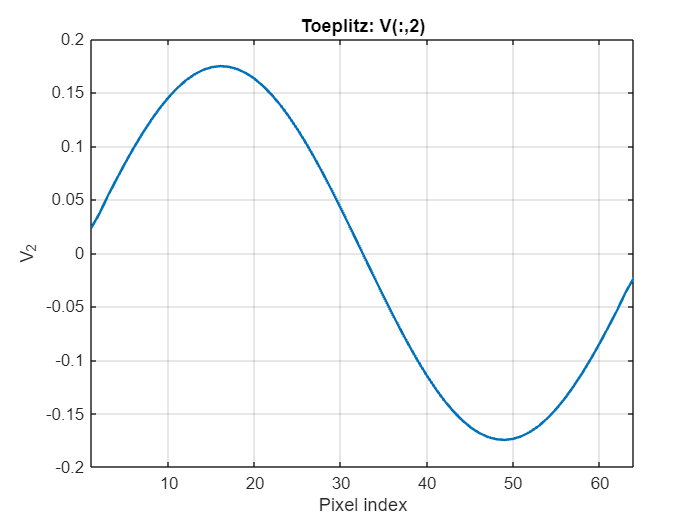

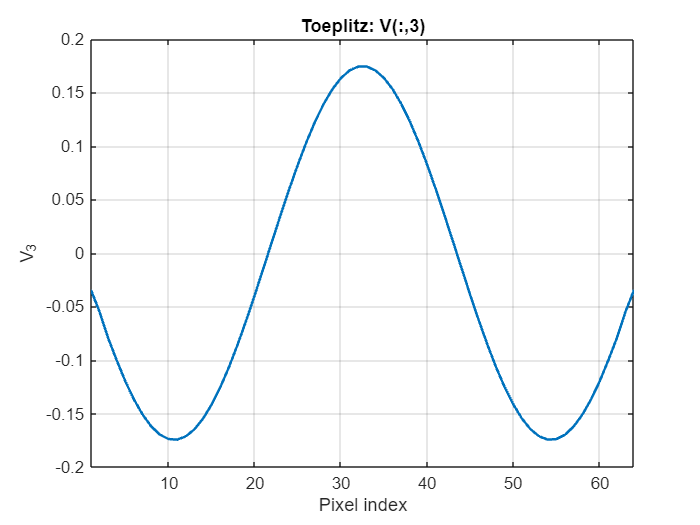

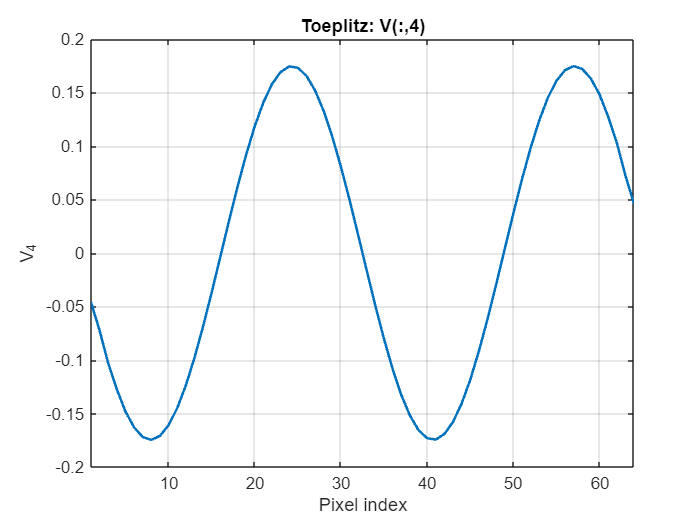


for k = 1:numCols
    figure;
    plot(x, V_toep(:,k), '-', 'LineWidth', 1.5);
    grid on;
    title(sprintf('Toeplitz: V(:,%d)', k));
    xlabel('Pixel index');
    ylabel(sprintf('V_{%d}', k));
    xlim([1 dim]);
end

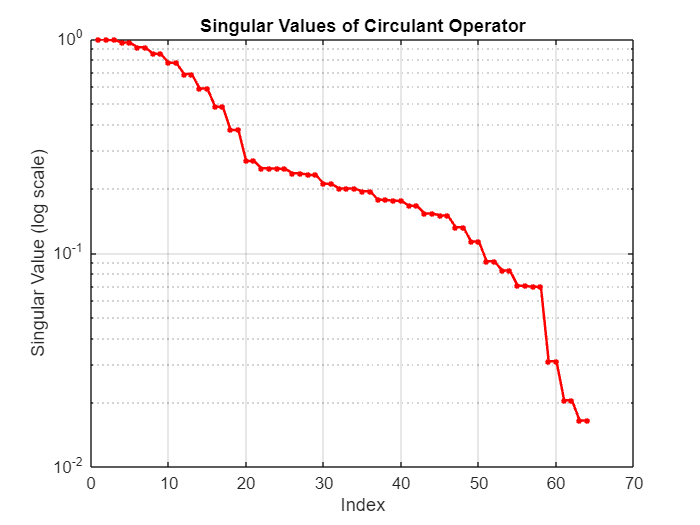


[U_circ, S_circ, V_circ] = svd(H_circulant);
sigma_circ = diag(S_circ);
figure;
semilogy(sigma_circ, 'r.-', 'LineWidth', 1.5, 'MarkerSize', 10);
grid on;
title('Singular Values of Circulant Operator');
xlabel('Index');
ylabel('Singular Value (log scale)');

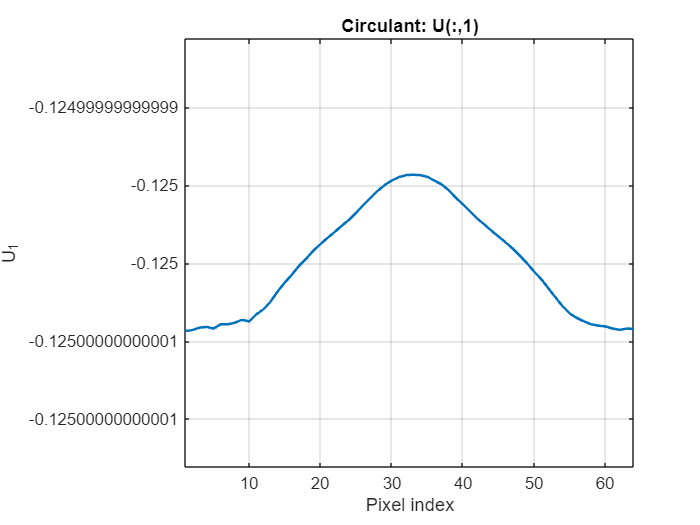

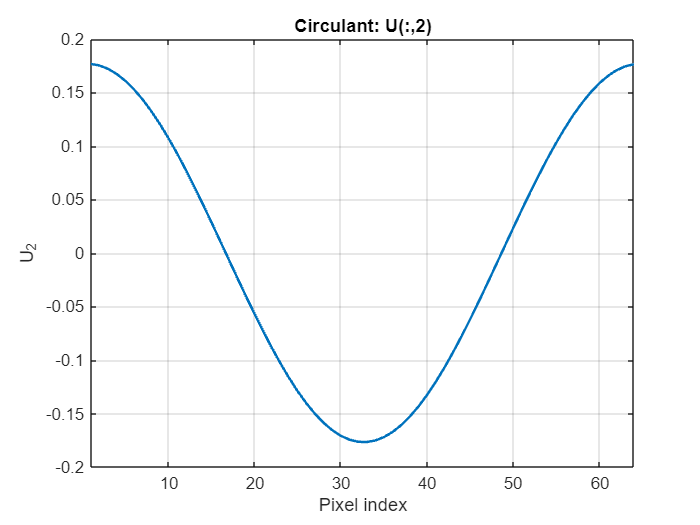

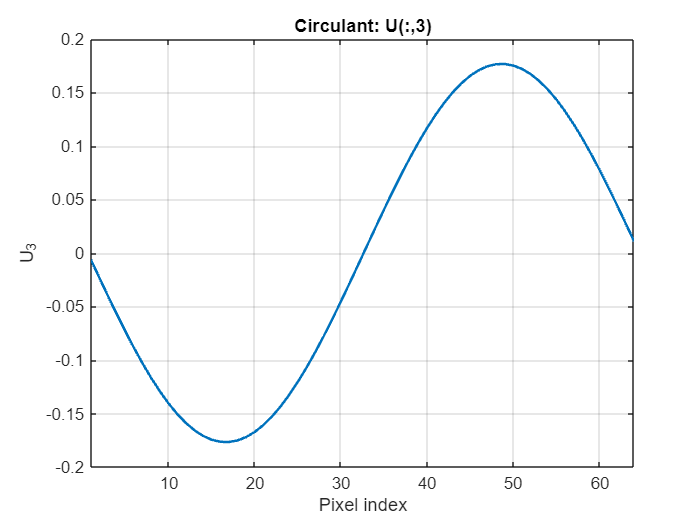

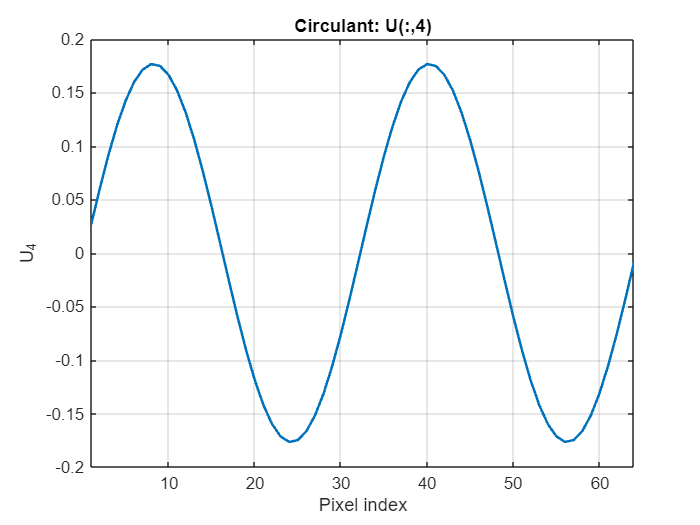


for k = 1:numCols
    figure;
    plot(x, U_circ(:,k), '-', 'LineWidth', 1.5);
    grid on;
    title(sprintf('Circulant: U(:,%d)', k));
    xlabel('Pixel index');
    ylabel(sprintf('U_{%d}', k));
    xlim([1 dim]);
end

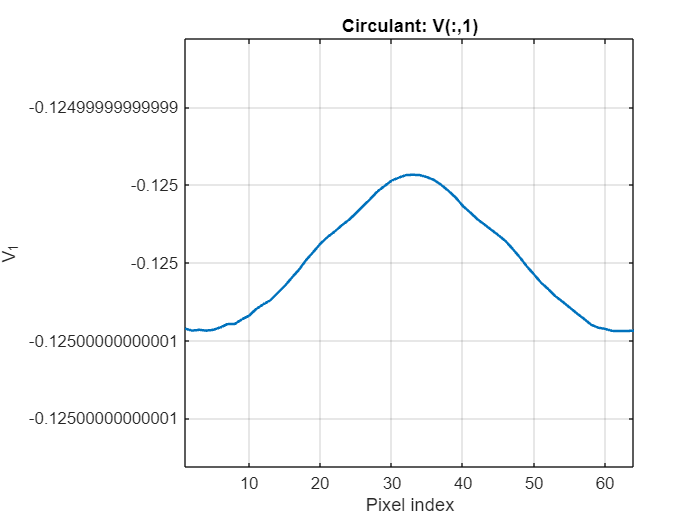

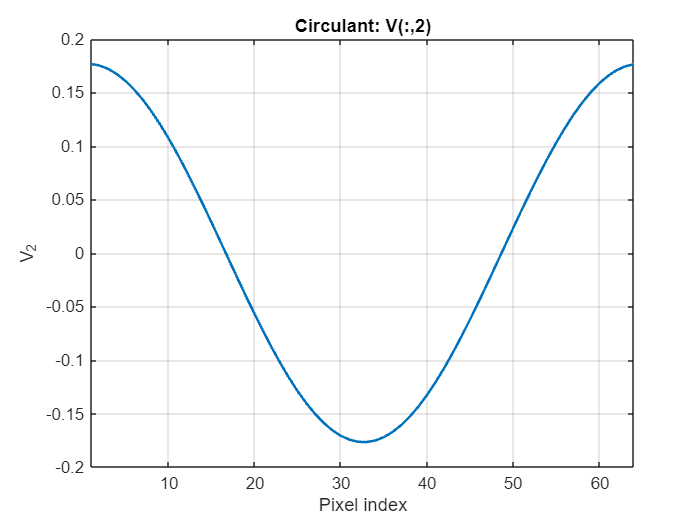

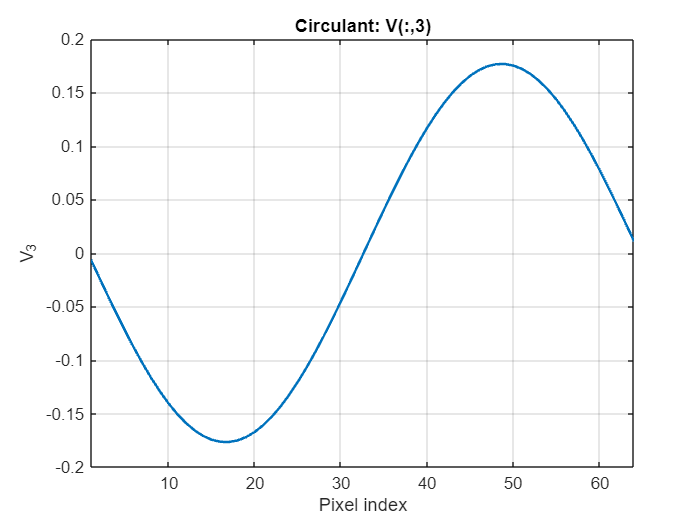

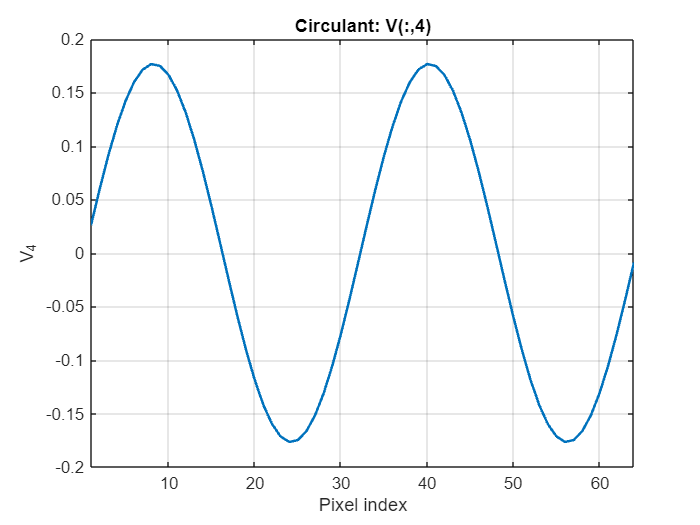


for k = 1:numCols
    figure;
    plot(x, V_circ(:,k), '-', 'LineWidth', 1.5);
    grid on;
    title(sprintf('Circulant: V(:,%d)', k));
    xlabel('Pixel index');
    ylabel(sprintf('V_{%d}', k));
    xlim([1 dim]);
end

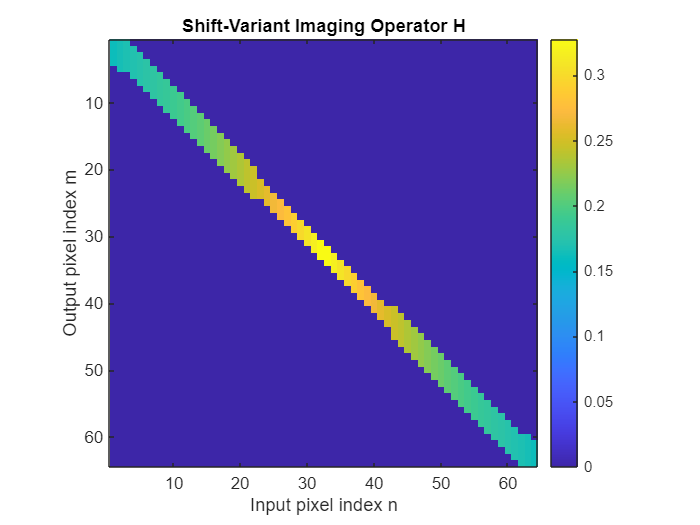

% 3.


% Constructed and visualized a shift-variant 1D imaging operator H
% whose point-spread is a rect of width w_n = alpha + beta*|n–32|
% and amplitude 1/w_n. 

dim   = 64;     
alpha = 3;       
beta  = 0.1;     
center = (dim+1)/2;
H = zeros(dim, dim);
for m = 1:dim
    for n = 1:dim
        w_n = alpha + beta*abs(n - center);  
        H(m,n) = (abs((m - n)/w_n) <= 1/2) * (1/w_n);
    end
end

figure;
imagesc(H);
colorbar;
title('Shift-Variant Imaging Operator H');
xlabel('Input pixel index n');
ylabel('Output pixel index m');
axis square;

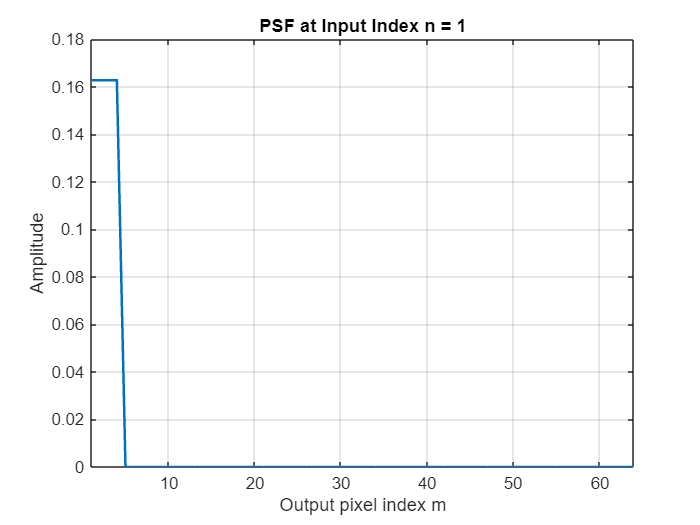

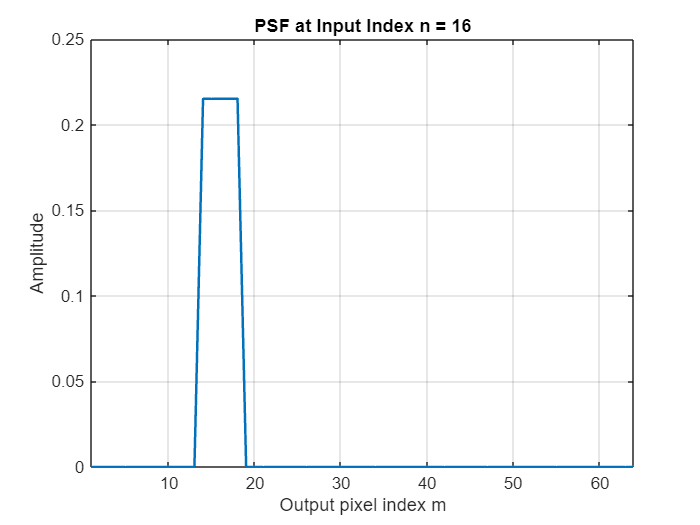

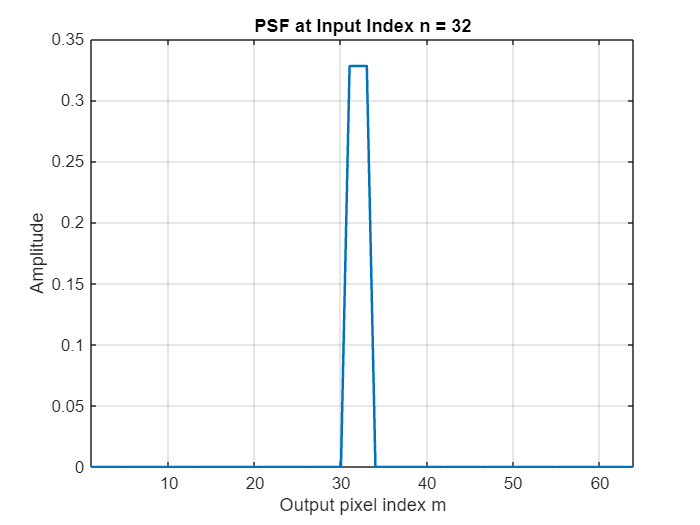

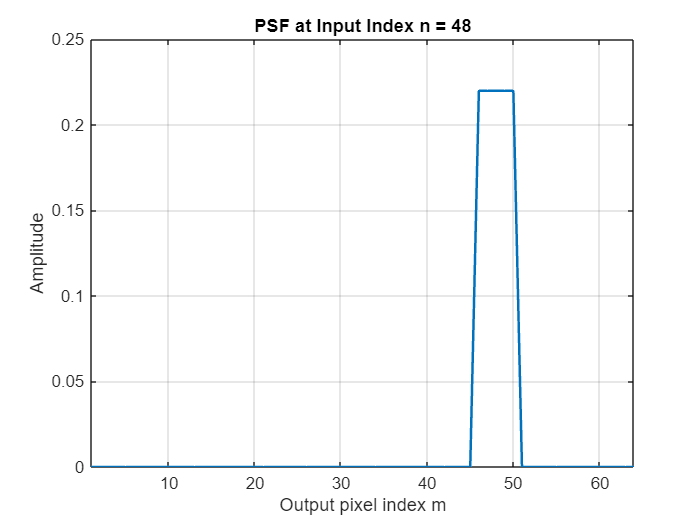

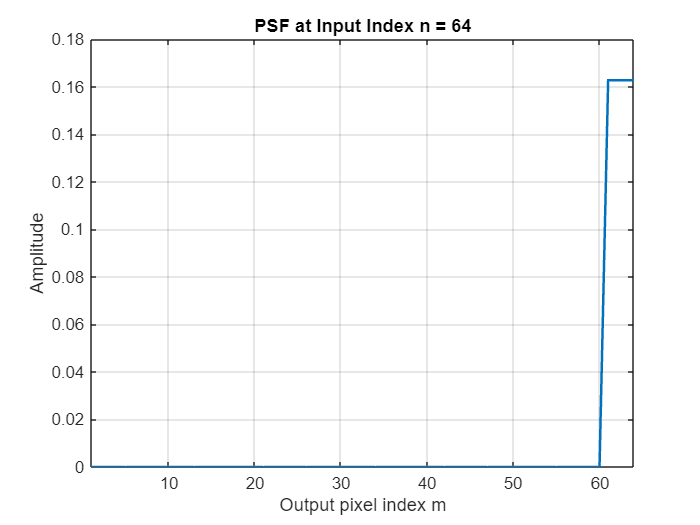


positions = [1, 16, 32, 48, 64]; 
for k = 1:length(positions)
    n0 = positions(k);
    h = H(:, n0); 
    figure;
    plot(1:dim, h, 'LineWidth', 1.5);
    grid on;
    title(sprintf('PSF at Input Index n = %d', n0));
    xlabel('Output pixel index m');
    ylabel('Amplitude');
    xlim([1 dim]);
end

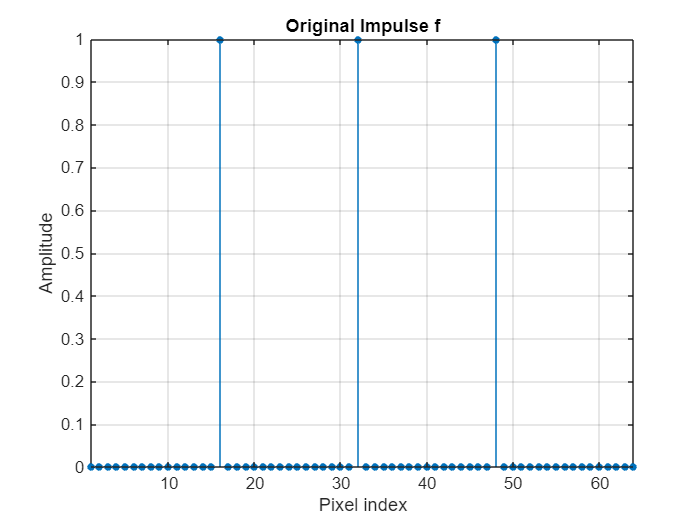


f = zeros(dim,1);
f([16,32,48]) = 1;   
g = H * f;            

figure;
stem(1:dim, f, 'filled','MarkerSize',4);
grid on;
title('Original Impulse f');
xlabel('Pixel index');
ylabel('Amplitude');
xlim([1 dim]);

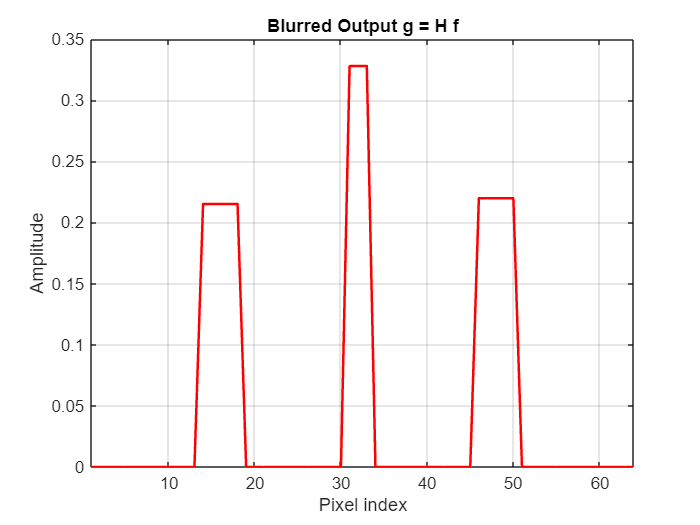


figure;
plot(1:dim, g, 'r-','LineWidth',1.5);
grid on;
title('Blurred Output g = H f');
xlabel('Pixel index');
ylabel('Amplitude');
xlim([1 dim]);

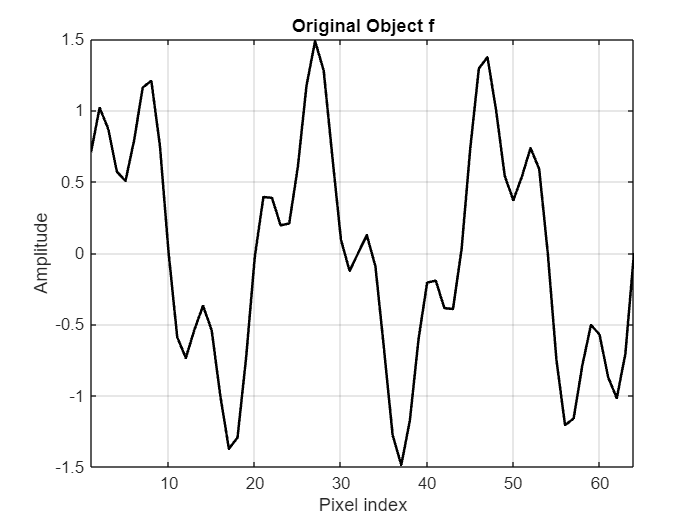

% 4.

% The singular values decay rapidly because H attenuates high frequencies.
% Inverting small singular values amplifies noise and numerical errors.
% Truncated SVD discards modes below 'tol', balancing resolution vs. stability.
% Too small tol gives overfitting noise; too large tol gives loss of detail.
% Practical deblurring requires selecting r to trade off blur removal and noise amplification.

dim   = 64;
alpha = 3;
beta  = 0.1;
center = (dim+1)/2;

H = zeros(dim,dim);
for m = 1:dim
    for n = 1:dim
        w_n = alpha + beta*abs(n-center);
        H(m,n) = (abs((m-n)/w_n) <= 1/2) * (1/w_n);
    end
end
x = (1:dim)';
f = sin(2*pi*3*x/dim) + 0.5*sin(2*pi*10*x/dim);
g = H * f;

figure;
plot(x, f, 'k-', 'LineWidth', 1.5);
grid on;
title('Original Object f');
xlabel('Pixel index');
ylabel('Amplitude');
xlim([1 dim]);

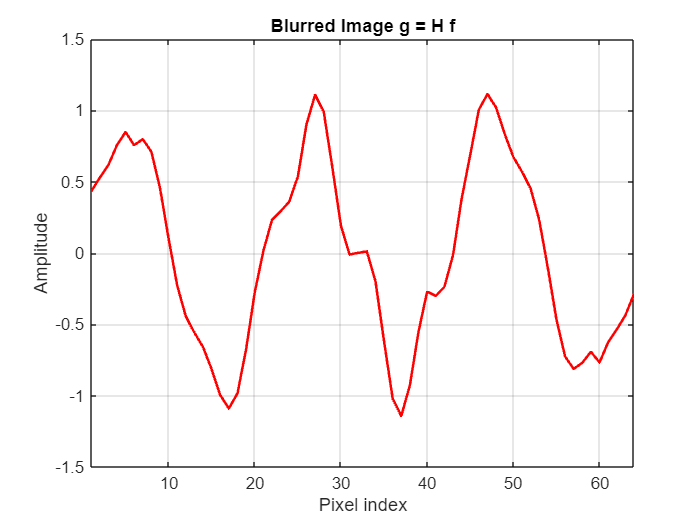


figure;
plot(x, g, 'r-', 'LineWidth', 1.5);
grid on;
title('Blurred Image g = H f');
xlabel('Pixel index');
ylabel('Amplitude');
xlim([1 dim]);

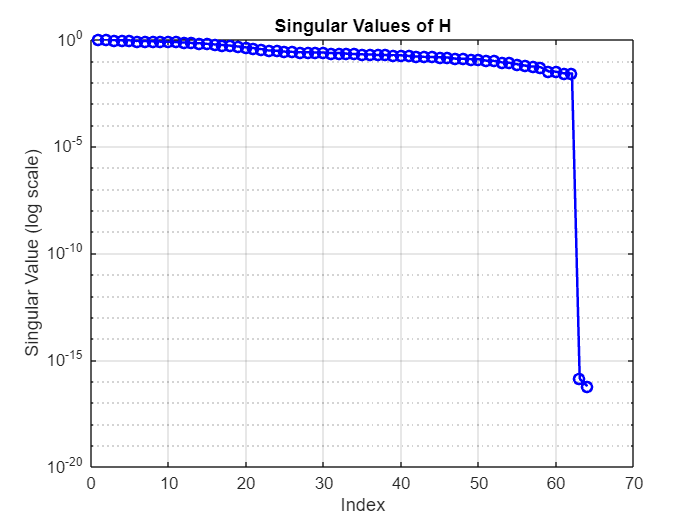


[U, S, V] = svd(H);
sing_vals = diag(S);

figure;
semilogy(sing_vals, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 6);
grid on;
title('Singular Values of H');
xlabel('Index');
ylabel('Singular Value (log scale)');

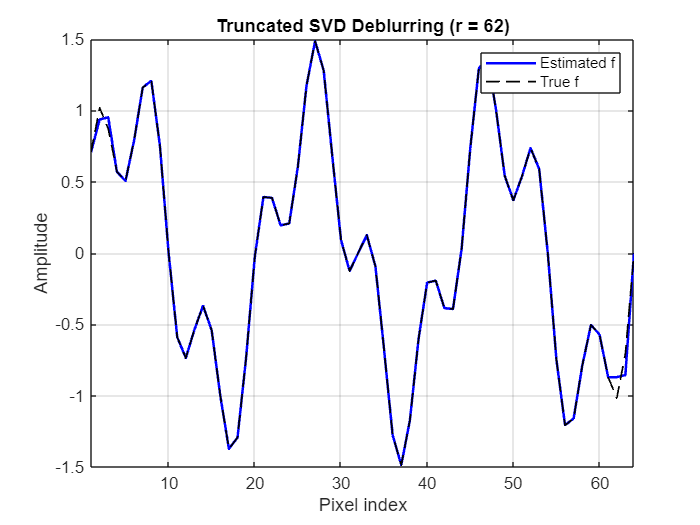


tol = 1e-2;               
r   = sum(sing_vals > tol);
S_inv = diag(1./sing_vals(1:r));
U_r    = U(:,1:r);
V_r    = V(:,1:r);
f_est  = V_r * S_inv * (U_r' * g);

figure;
plot(x, f_est, 'b-', 'LineWidth', 1.5);
hold on;
plot(x, f, 'k--', 'LineWidth', 1);
grid on;
title(sprintf('Truncated SVD Deblurring (r = %d)', r));
xlabel('Pixel index');
ylabel('Amplitude');
legend('Estimated f','True f');
xlim([1 dim]);

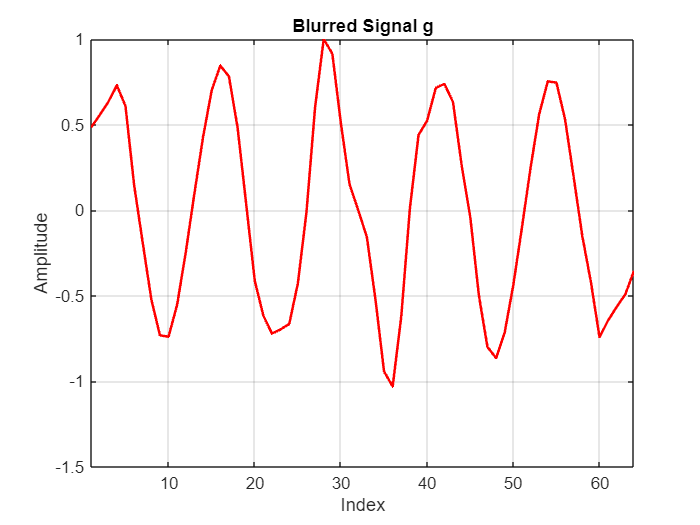

% 5.


% The singular values illustrate which modes of H are invertible.
% Truncating at sigma > tol avoids amplifying noise in small modes.
% r controls the balance: larger r recovers more detail but risks noise.
% If g contains measurement noise, small singular modes inflate errors.

dim    = 64;
alpha  = 3;
beta   = 0.1;
center = (dim+1)/2;
tol    = 1e-2;    
x = (1:dim)';
f_true = sin(2*pi*5*x/dim) + 0.5*sin(2*pi*12*x/dim);
H = zeros(dim);
for m = 1:dim
    for n = 1:dim
        w_n    = alpha + beta*abs(n-center);
        H(m,n) = (abs((m-n)/w_n) <= 1/2)*(1/w_n);
    end
end
g = H*f_true; 

figure;
plot(1:dim, g, 'r-', 'LineWidth', 1.5);
grid on;
title('Blurred Signal g');
xlabel('Index');
ylabel('Amplitude');
xlim([1 dim]);

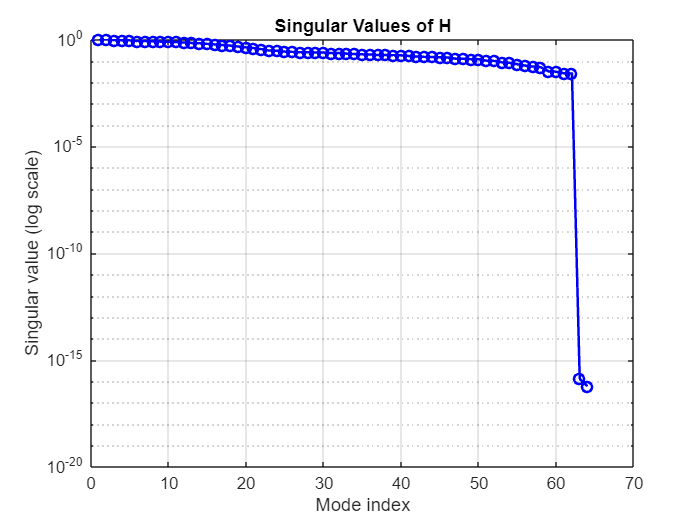


[U, S, V] = svd(H);
sigma = diag(S);

figure;
semilogy(sigma, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 6);
grid on;
title('Singular Values of H');
xlabel('Mode index');
ylabel('Singular value (log scale)');

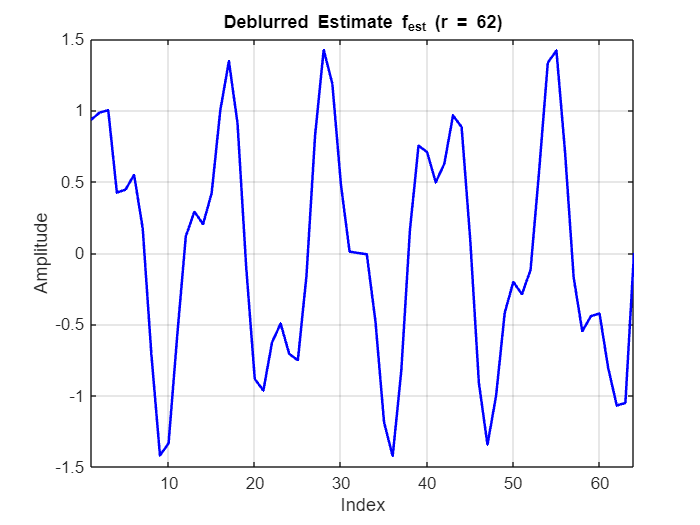


r = sum(sigma > tol);
U_r   = U(:,1:r);
S_inv = diag(1./sigma(1:r));
V_r   = V(:,1:r);
f_est = V_r * (S_inv * (U_r' * g));

figure;
plot(1:dim, f_est, 'b-', 'LineWidth', 1.5);
grid on;
title(sprintf('Deblurred Estimate f_{est} (r = %d)', r));
xlabel('Index');
ylabel('Amplitude');
xlim([1 dim]);

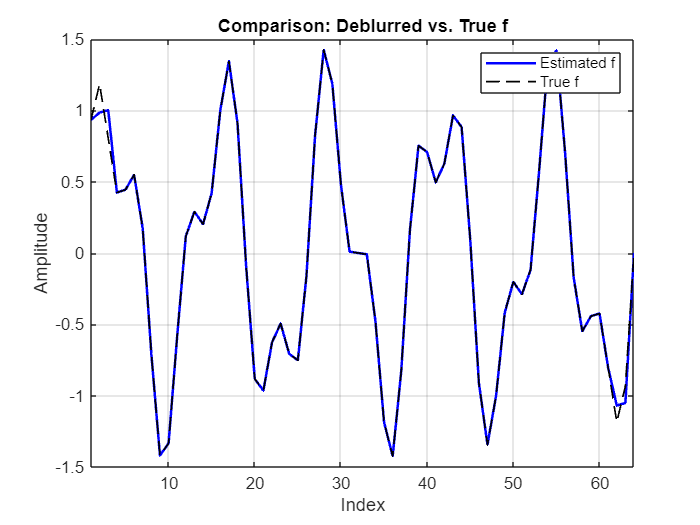


if exist('f_true','var')
    figure;
    plot(1:dim, f_est, 'b-', 'LineWidth', 1.5);
    hold on;
    plot(1:dim, f_true, 'k--', 'LineWidth', 1);
    grid on;
    title('Comparison: Deblurred vs. True f');
    xlabel('Index');
    ylabel('Amplitude');
    legend('Estimated f','True f');
    xlim([1 dim]);
end